# German Stocks - Importing II

## 1.

Open `DAX.xls` in Excel.  This file contains price series information from the German stock index DAX as well as its 30 constituent stocks. Included are their names as column headers as well as date information in the first column.

openvar('DAX.xls')

## 2.

Import the data into a table.  Use the stock/index names as variable names.

dax = readtable('DAX.xls');

## 3.

Remove all corrupted observations (one or more values missing within one row).

dax = rmmissing(dax)

dax = 891×32 table
       Date        DAX      Adidas    Allianz    BASF     Bayer    Beiersdorf     BMW     Commerzbank    Daimler    DeutscheBank    DeutscheBahn    Lufthansa    DeutschePost    DeutscheTelekom     EON     FreseniusMedical    Fresenius    Heidelberger    Henkel    Infineon    Salzgitter    Linde     MAN      MRK     Metro    MunichRe     RWE      SAP     Siemens    ThyssenKrupp     VW  
    __________    _____

## 4.

Flip the data vertically such that the latest data is at the bottom.

dax = flipud(dax)

dax = 891×32 table
       Date        DAX      Adidas    Allianz    BASF     Bayer    Beiersdorf     BMW     Commerzbank    Daimler    DeutscheBank    DeutscheBahn    Lufthansa    DeutschePost    DeutscheTelekom     EON     FreseniusMedical    Fresenius    Heidelberger    Henkel    Infineon    Salzgitter    Linde     MAN      MRK     Metro    MunichRe     RWE      SAP     Siemens    ThyssenKrupp     VW  
    __________    _____

## 5.

Convert all price series to log return series using the formula

  `logReturns`` = diff(log(prices)) `

**Hint** Try to use the `varfun` function.

daxReturns = varfun(@(x) diff(log(x)),dax,'InputVariables',dax.Properties.VariableNames(2:end));
%  Use the same variable names (default names returned from varfun are funky)
daxReturns.Properties.VariableNames = dax.Properties.VariableNames(2:end)

daxReturns = 890×31 table
       DAX          Adidas        Allianz         BASF          Bayer       Beiersdorf        BMW        Commerzbank     Daimler      DeutscheBank    DeutscheBahn    Lufthansa     DeutschePost    DeutscheTelekom       EON        FreseniusMedical    Fresenius     Heidelberger      Henkel       Infineon     Salzgitter      Linde          MAN           MRK          Metro        MunichRe          RWE           SAP          Siemens      ThyssenKrupp        

## 6.

Use the date information of the price series as row names for the return series.

daxReturns.Properties.RowNames = cellstr(datestr(dax.Date(2:end)))

daxReturns = 890×31 table
                      DAX          Adidas        Allianz         BASF          Bayer       Beiersdorf        BMW        Commerzbank     Daimler      DeutscheBank    DeutscheBahn    Lufthansa     DeutschePost    DeutscheTelekom       EON        FreseniusMedical    Fresenius     Heidelberger      Henkel       Infineon     Salzgitter      Linde          MAN           MRK          Metro        MunichRe          RWE           SAP          Siemens      ThyssenKrupp 

## 7.

Save the return series table in a file named `daxReturns.mat`.

save('daxReturns.mat','daxReturns');

## 8.

Plot the returns for the variables `BMW`, `Daimler`, and `VW` against date.

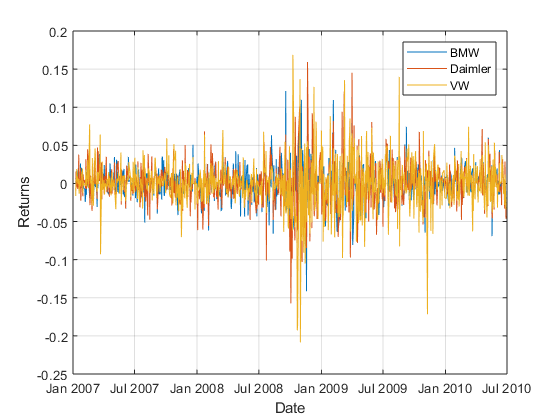

dax.Date = datetime(dax.Date,'InputFormat','MM/dd/yyy');
plot(dax.Date(1:end-1),daxReturns{:,{'BMW','Daimler','VW'}})
grid('on')
legend('BMW','Daimler','VW')
xlabel('Date')
ylabel('Returns')